# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 채정인**

**학번**** : 201917114**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 


x = [1,2,2,1]; N=4 ; X = fft(x,N) %DFT 결과값 

X =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 + 0.0000i  -1.0000 + 1.0000i



ix = ifft(X)

ix =      1     2     2     1


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x2 = [1,2,2,1,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0,0]; N=16 ; X2 = fft(x2,N) %DFT 결과값 

X2 =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i


ix2 = ifft(X2)

ix2 =     1.0000    2.0000    2.0000    1.0000   -0.0000   -0.0000         0    0.0000    0.0000    0.0000         0    0.0000    0.0000   -0.0000         0   -0.0000


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

%DFS의 계수는 N값과 같음 즉 4
xtilde1 = [4,1,-1,1]; N=4 ; Xtilde1 = fft(xtilde1,N)

Xtilde1 =      5     5     1     5


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

%DFS 계수는 5 
xtilde2 = [1,0,-1,-1,0]; N=5 ; Xtilde3 = fft(xtilde2,N)

Xtilde3 =    -1.0000    2.6180    0.3820    0.3820    2.6180


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

n = 0:100;, xn = sinc((n-50)/2).^2; N = length(xn);
Xk = fft(xn, N); k = 0:N-1;
mag_Xk =abs(Xk); pha_Xk = angle(Xk)*180/pi;
zei = find(mag_Xk< 0.00001);
pha_Xk(zei)=zeros(1,length(zei))

pha_Xk =          0 -178.2178    3.5644 -174.6535    7.1287 -171.0891   10.6931 -167.5248   14.2574 -163.9604   17.8218 -160.3960   21.3861 -156.8317   24.9505 -153.2673   28.5149 -149.7030   32.0792 -146.1386   35.6436 -142.5743   39.2079 -139.0099   42.7723 -135.4455   46.3366 -131.8812   49.9010 -128.3168   53.4653 -124.7525   57.0297 -121.1881   60.5941 -117.6238   64.1584 -114.0594   67.7228 -110.4950   71.2871 -106.9307   74.8515 -103.3663   78.4158  -99.8020   81.9802  -96.2376   85.5446  -92.6733



Hf_1 = figure('Units','normalized','position',[0.1,0.1,0.8,0.8],...
    'color',[0,0,0],'paperunits','inches','paperposition',[0,0,6,5]);
set(Hf_1,'NumberTitle','off','name','P5.8');

subplot(2,1,1); H_s1 = stem(k,mag_Xk,'filled'); set(H_s1,'markersize',3);
set(gca,'XTick',[0:20:N],'fontsize',8);axis([0,N,0,2.5])
set(gca,'YTick',[0:0.5:2.5],'fontsize',8);ylabel('Magnitude');
title('Magnitude plots of DFT and DTFT','fontsize',10);hold on

subplot(2,1,2); H_s2 = stem(k,pha_Xk,'filled'); set(H_s2,'markersize',3);
set(gca,'XTick',[0:20:N],'fontsize',8);axis([0,N,-200,200])
set(gca,'YTick',[-180:-90:0:90:180],'fontsize',8);
ylabel('k');ylabel('Degrees');
title('Phase plots of DFT and DTFT','fontsize',10);hold on




2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

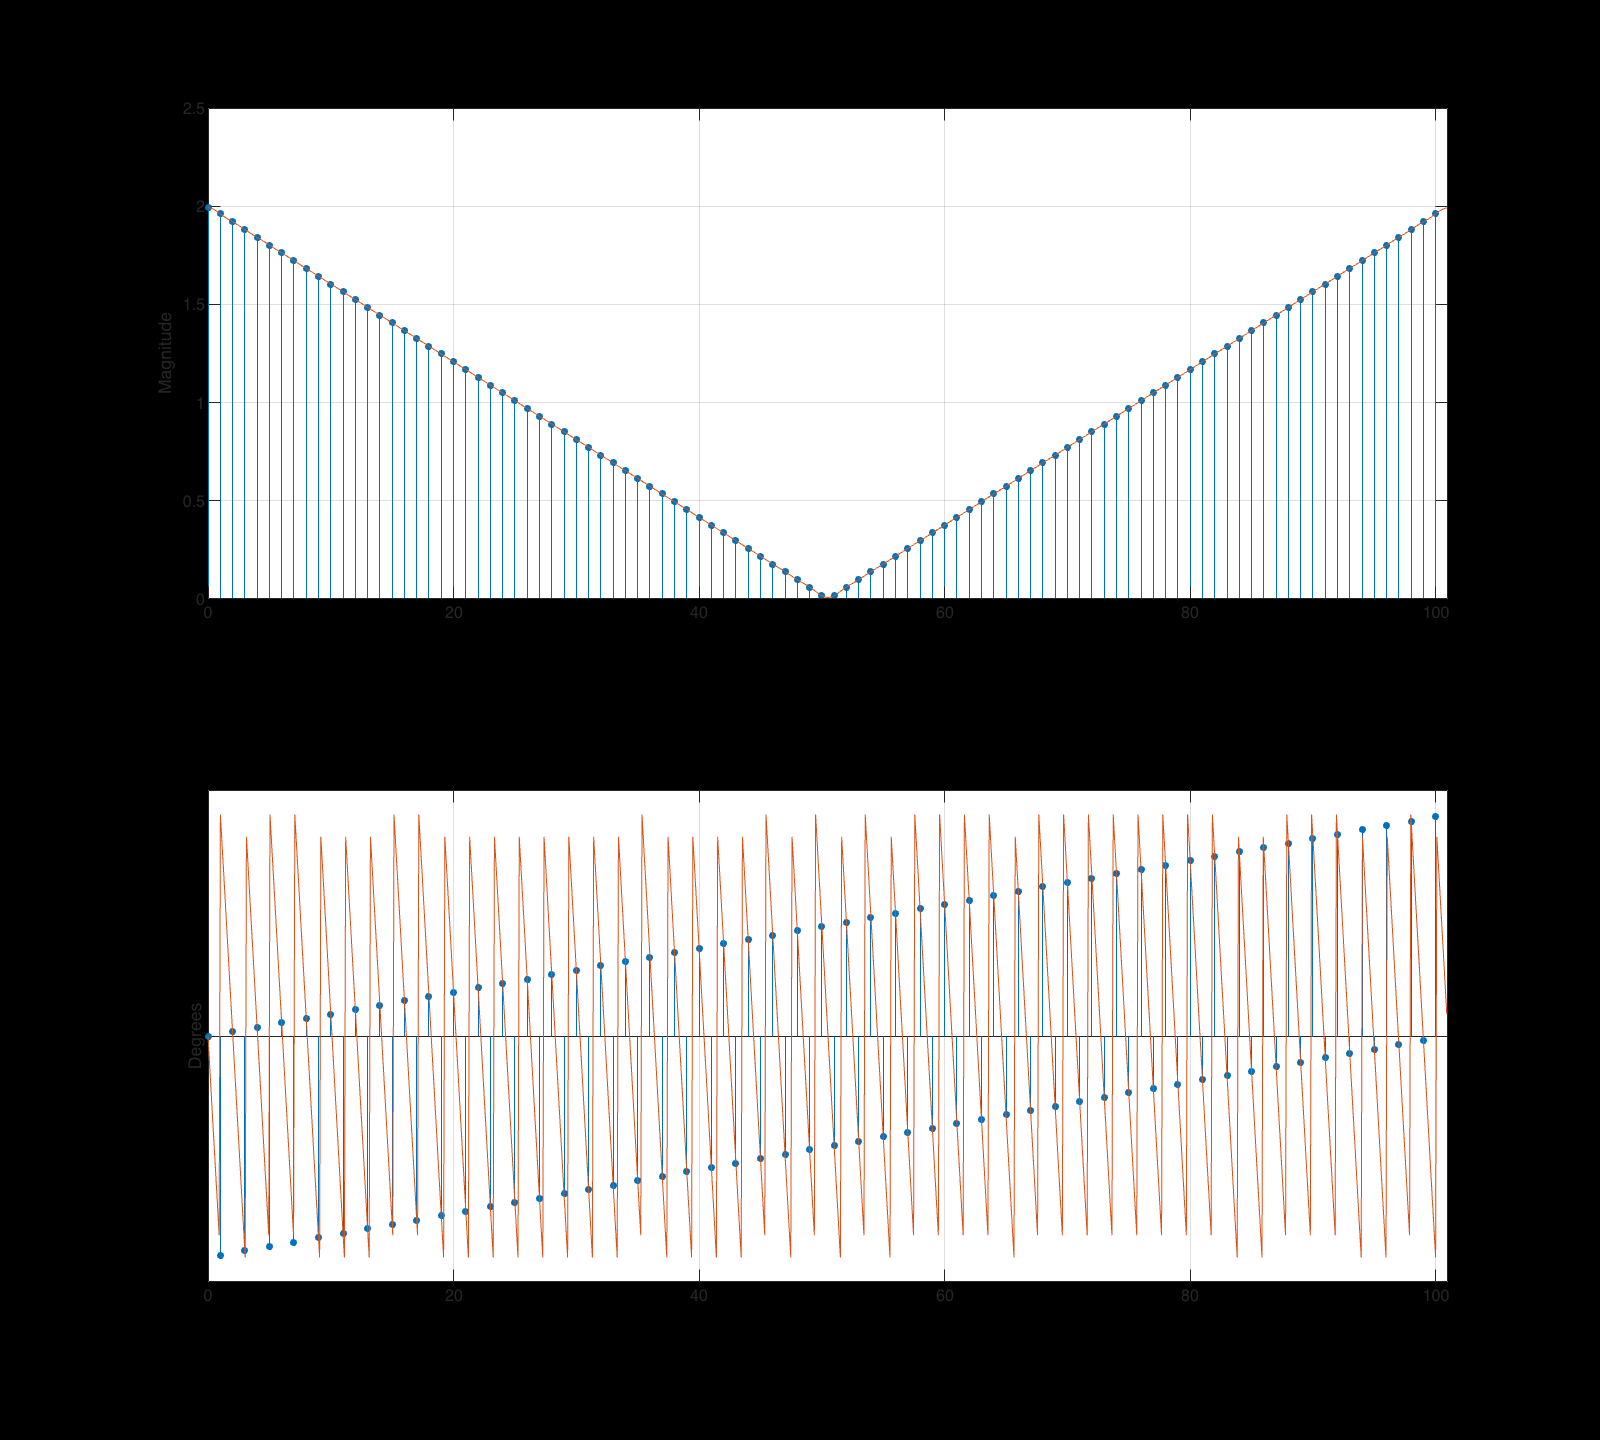

[X,w] = freqz(xn,1,1000,'whole');
mag_X = abs(X); pha_X = angle(X)*180/pi;
Dw = (2*pi)/N;

subplot(2,1,1);plot(w/Dw,mag_X); grid
hold off
subplot(2,1,2);plot(w/Dw,pha_X); grid
hold off

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

%1),2) 에 hold on hold off 를 이용하여 하나의 그래프에 나타내었다. 두 그래프가 겹쳐지는 것을 확인할 수 있고
%이로부터 샘플링 변형임을 검증한다. 



4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

%재구성할 수 있다. N값과 신호의 크기가 같으면 주파수 샘플링 정리에 의해 재구성할 수 있기 때문이다. 

보간 공식은 아래와 같이 나타낼 수 있다. 

X(e^jw) = $\sum_{n=-\infty }^{\infty } X\left(k\right)\phi \left(w-2*\mathrm{pi}*\frac{k}{N}\right)\;$